# Calcualtion of Intra Hamming Distance of Power Measurements

 (C) 2021, Juan Esteban Villegas, NYUAD

Data available for one device with design type 2. We compute intra HD distances for all devices comapred always to the first measurements (0 dB attenuation). 

First extract the data from the H5 files. 

folder = '..\Datasets\';
clear files
files{1} = 'dev20_Au1_Chips02_02_TM_InputPowerSweep.h5';

%Data is tagged using var(1) as the device index and var(2) as the port
%index. We comapre only the drop ports in the design 3 type of devices.
filename = strcat(folder,files{1});
struct = h52struct(filename);
meas = struct.project.measurements; 
dataset=[];

for i = 1:length(meas)
    m = meas(i).spectra;
    dataset(:,i) = m(:,2);
    lambda = m(:,1);
end
pow = [meas.var]'; 
pow = pow(1:3:end);

clear('result_ref','result_shf');
L=0.03; mode = 'all';

for i = 2:size(dataset,2)
    idx1 = 1; 
    idx2 = i; 
    
    data1 = dataset(:,idx1);   data1 = data1-max(data1);
    data2 = dataset(:,idx2);   data2 = data2-max(data2);
    if i==38
       disp('here')
    end
    [data1_s, data2_s, lambda_c] = shiftSpectra(data1,data2,lambda);

    result_ref(i-1,:) = LHD_Compute(lambda, [data1, data2], mode, L);
    result_shf(i-1,:) = LHD_Compute(lambda_c, [data1_s, data2_s], mode, L);
end
avg =  mean(result_shf); sigma = std( result_shf);
disp(   sprintf("Average LHD=%02.3f\x00B1%02.3f",avg(3), sigma(3)))  ;
disp(   sprintf("Average BHD=%02.3f\x00B1%02.3f",avg(4), sigma(4)))  ;

## **Now the plots**

We will use 'x' to mark average raw devices and 'o' to mark the responses shifted in spectrum.  

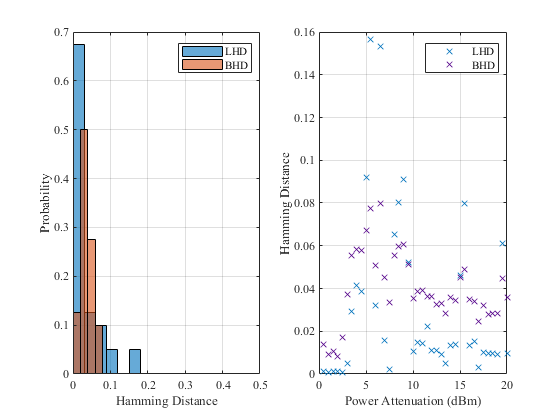

figure, clf;  titles = {'','',''};
colors = ['b','b','b']; colors_s = ['r','r','r'];

subplot(1,2,1);
histogram(result_shf(:,3),'normalization','Probability'); 
hold on, histogram(result_shf(:,4),'normalization','Probability');
xlabel('Hamming Distance'); ylabel('Probability');
set(gca,'fontname','times') ; grid on;

legend({'LHD' 'BHD'});
xlim([0 0.5]); 

subplot(1,2,2);
plot(pow(2:end), result_ref(:,3),'x'); 
hold on, 
%h = plot(pow(2:end), result_shf(:,3),'o'); 
%h.Annotation.LegendInformation.IconDisplayStyle = 'off';

h = plot(pow(2:end), result_ref(:,4),'x'); 
h.Color = '#57068c';
hold on, 
%h = plot(pow(2:end), result_shf(:,4),'o'); 
%h.Annotation.LegendInformation.IconDisplayStyle = 'off';
xlabel('Power Attenuation (dBm)'); ylabel('Hamming Distance');
set(gca,'fontname','times') ; grid on;

legend({'LHD' 'BHD'});